%---stabilizzazione con u = -k*x con stato stimato, parte di "Tesina MFC"---
% sistema massa-molla-smorzatore

% parametri
m = 10; c = -0.5; k = 2; %m=massa, c=coef. di attrito, k=cost. elastica

A = [0 1; -k/m -c/m];
B = [0; 1/m];
C = [1 0];
D = 0;

sys = ss(A, B, C, D);
sys_tf = tf(sys); %fdt

display(sys);


sys =
 
  A = 
         x1    x2
   x1     0     1
   x2  -0.2  0.05
 
  B = 
        u1
   x1    0
   x2  0.1
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


display(sys_tf);


sys_tf =
 
         0.1
  ------------------
  s^2 - 0.05 s + 0.2
 
Continuous-time transfer function.



%diagonalizzabilità
[A_V, A_D] = eig(sys.A);
disp('Autovalori di A: ');

Autovalori di A: 


disp(A_D);

   0.0250 + 0.4465i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0250 - 0.4465i



if rank(A_V) == size(sys.A)
    disp('La matrice A è diagonalizzabile');
else
    disp('La matrice A non è diagonalizzabile');
end

La matrice A è diagonalizzabile



Cb = ctrb(sys.A, B); %matrice di controllabilità
r_Cb = rank(Cb);
if r_Cb == size(sys.A, 1)
    disp('Il sistema è completamente raggiungibile');
else
    disp('Il sistema non è completamente raggiungibile');
end

Il sistema è completamente raggiungibile


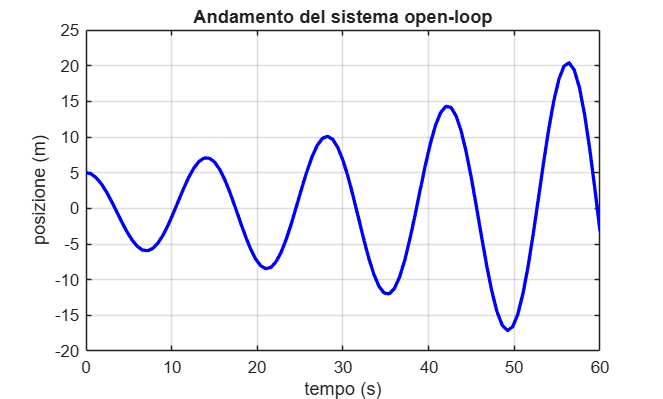


% simulazione
x0 = [5; 0];
t_finale = 60;
[y, t] = initial(sys, x0, t_finale);

figure;
% plot della Posizione (x1 / y)
plot(t, y, 'b', 'LineWidth', 2);
ylabel('posizione (m)');
xlabel('tempo (s)');
title('Andamento del sistema open-loop');
grid on;


p = [-0.5, -1.5];
K = place(sys.A, sys.B, p);
display(K); % guadagno K

K =     5.5000   20.5000



p_obs = [-2, -3]; % più veloci
L_trasposto = place(sys.A', sys.C', p_obs);
L = L_trasposto'; 
display(L); % guadagno L

L =     5.0500
    6.0525



% thm di separazione
Acl = [sys.A-sys.B*K, B*K; 
       zeros(size(sys.A)), sys.A-L*sys.C];

eig_cl = eig(Acl);
disp('Autovalori del sistema a ciclo chiuso:');

Autovalori del sistema a ciclo chiuso:


disp(sort(eig_cl));

   -3.0000
   -2.0000
   -1.5000
   -0.5000



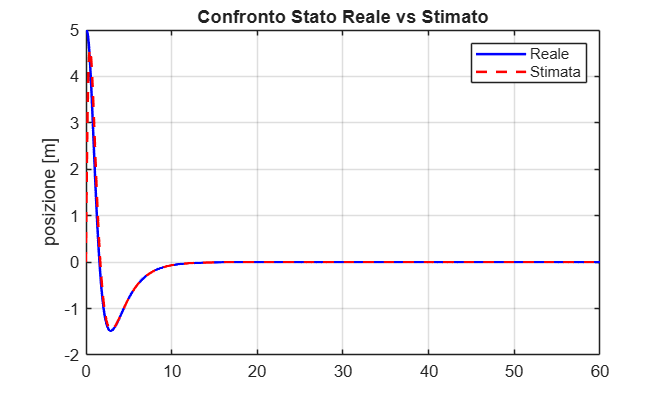


Bcl = [B; 0; 0];
Ccl = [C, 0, 0];
Dcl = 0;

sys_cl = ss(Acl, Bcl, Ccl, Dcl);

% simulazione
x0 = [5; 0];
x0_obs = [0; 0];
x0_tot = [x0; (x0 - x0_obs)]; % stato cl z = [x; e]

t_finale = 60;
[y, t, x] = initial(sys_cl, x0_tot, t_finale);

x_reale = x(:, 1:2);
e = x(:, 3:4);

% x_stimato = x_reale - errore
x_stimato = x_reale - e;

figure;
% posizione reale vs stimata
plot(t, x_reale(:,1), 'b', 'LineWidth', 1.5); hold on;
plot(t, x_stimato(:,1), 'r--', 'LineWidth', 1.5);
grid on;
ylabel('posizione [m]');
legend('Reale', 'Stimata');
title('Confronto Stato Reale vs Stimato');

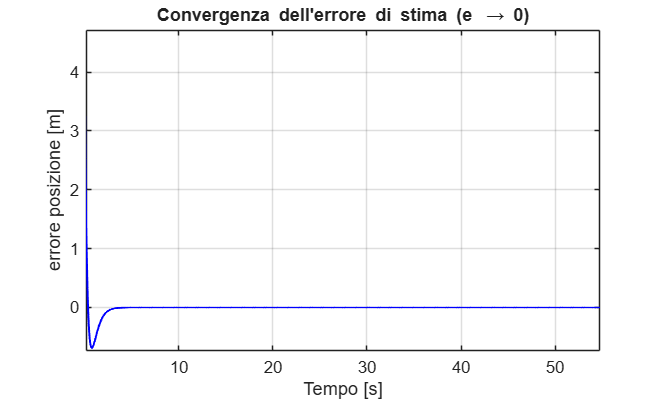


% errore di stima
figure;
plot(t, e(:,1), 'b', 'LineWidth', 1.2);
grid on;
xlabel('Tempo [s]');
ylabel('errore posizione [m]');
title('Convergenza dell''errore di stima (e \rightarrow 0)');